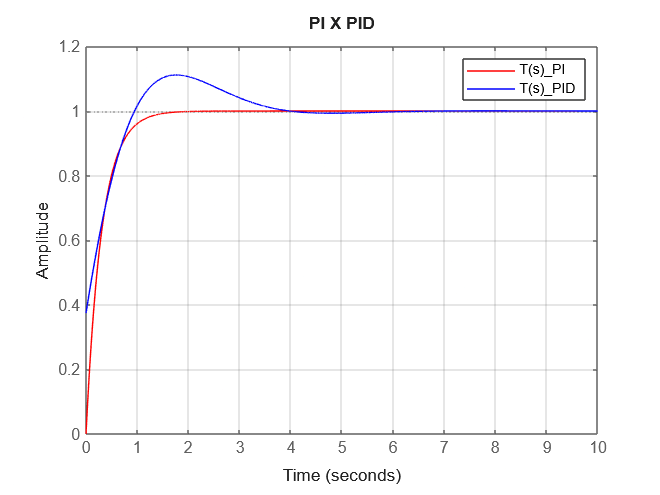

clc; clear; close all 
s = tf('s');

% parametros da planta
b = 3.235;
a = 0.226;
% funçao da planta
G_p = b/((s+a));

% parametros PI 
    PI_kp = 1;
    PI_ki = a*PI_kp;
    
    % funçao do controlador PI
    C_PI = (PI_kp*s+PI_ki)/s;
    % FTMF por cancelamento de polos e zeros
    T_PI = b*PI_kp/(s+b*PI_kp);


% parametros PID
        T = 4.42;
        L = 0.442;
        
        PID_kp = 0.837;
        
        % ganho integral
        ti = 0.884;
        PID_ki = PID_kp/ti;
        
        % ganho derivativo
        td = 0.221;
        PID_kd = PID_kp*td;
    
    % funçao do controlador PID
    C_PID = (s^2*PID_kd + s*PID_kp + PID_ki)/s;
    % FTMF do controlador PID
    L_PID = G_p*C_PID;
    T_PID = L_PID/(1+L_PID);

hold on
    figure(1)
    % plot resposta PI
    step(T_PI,'r',0:0.001:10)
    axis([0 10 0 1.2]);
    grid on
    
    % plot resposta PID
    step(T_PID,'b',0:0.001:10)
    axis([0 10 0 1.2]);
    grid on
    title('PI X PID')
    legend('T(s)_PI', 'T(s)_PID')
hold off


PI_info = stepinfo(T_PI)

PI_info = struct with fields:
         RiseTime: 0.6791
    TransientTime: 1.2093
     SettlingTime: 1.2093
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 2.2634


PID_info = stepinfo(T_PID)

PID_info = struct with fields:
         RiseTime: 0.7011
    TransientTime: 3.5486
     SettlingTime: 3.3733
      SettlingMin: 0.9007
      SettlingMax: 1.1116
        Overshoot: 11.1554
       Undershoot: 0
             Peak: 1.1116
         PeakTime: 1.7564
